# Preprocess Data

Instructions are in the task pane to the left. Complete and submit each task one at a time.

Do not edit. This code loads the data.

letter = readtable("M.xlsx")

letter = 41×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    13734    0.736    0.332    0.026
    13735    0.736    0.333    0.095
    13735    0.736    0.333    0.095
    13749    0.735    0.334    0.284
    13766    0.735    0.328    0.515
    13782    0.735    0.318    0.763
    13799    0.736    0.299    0.983
    13817    0.737    0.284        1
    13832    0.738    0.268        1
    13850    0.738    0.258        1
    13867    0.738    0.253        1
    13883    0.739    0.253        1
    13899    0.739    0.256        1
    13916    0.739    0.268        1
    13933     0.74    0.286        1
    13949    0.742    0.304        1


## Task 1

You can use dot notation to extract, modify, and reassign variables in a table, just as you would with any variable.  

For example, this code adds 3 to each value in the variable `x`.

`x` `=` `x` `+` `3``;`  

This corresponding code adds 3 to each value in the `XVal` column of the table `data`. 

`data.XVal` `=` `data.XVal` `+` `3``;`

Task

Multiply the values in the `X` variable of the table `letter` by an aspect ratio of 1.5. Reassign the result back to `X` so that `letter` contains the corrected data.

letter.X=letter.X*1.5

letter = 41×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

    13734     1.104    0.332    0.026
    13735     1.104    0.333    0.095
    13735     1.104    0.333    0.095
    13749    1.1025    0.334    0.284
    13766    1.1025    0.328    0.515
    13782    1.1025    0.318    0.763
    13799     1.104    0.299    0.983
    13817    1.1055    0.284        1
    13832     1.107    0.268        1
    13850     1.107    0.258        1
    13867     1.107    0.253        1
    13883    1.1085    0.253        1
    13899    1.1085    0.256        1
    13916    1.1085    0.268        1
    13933      1.11    0.286        1
    13949     1.113    0.304        1


View the result

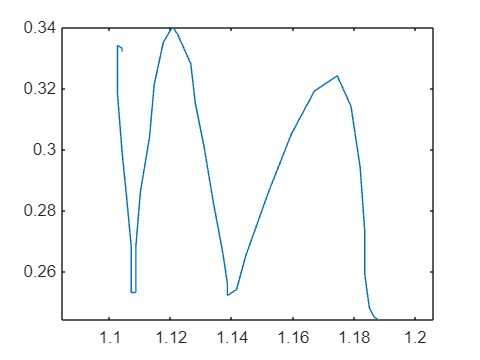

plot(letter.X,letter.Y)
axis equal

## Task 2

You can index into variables in a table by using dot notation and parentheses.

`finalX` `=` `data.XVal``(``end``)``;`

Task

Shift the `Time` variable of the table `letter` so it starts at 0, and convert the values from milliseconds to seconds. Assign the result back to `Time` so that `letter` contains the adjusted data.

letter.Time=(letter.Time-letter.Time(1))/1000

letter = 41×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0     1.104    0.332    0.026
    0.001     1.104    0.333    0.095
    0.001     1.104    0.333    0.095
    0.015    1.1025    0.334    0.284
    0.032    1.1025    0.328    0.515
    0.048    1.1025    0.318    0.763
    0.065     1.104    0.299    0.983
    0.083    1.1055    0.284        1
    0.098     1.107    0.268        1
    0.116     1.107    0.258        1
    0.133     1.107    0.253        1
    0.149    1.1085    0.253        1
    0.165    1.1085    0.256        1
    0.182    1.1085    0.268        1
    0.199      1.11    0.286        1
    0.215     1.113    0.304        1


View the result

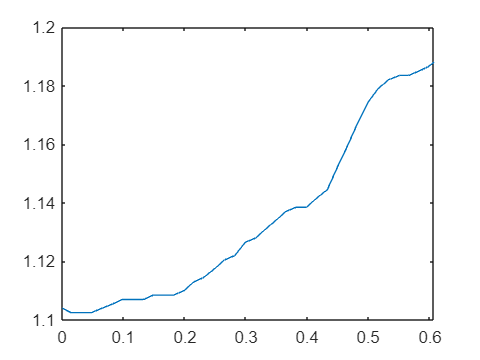

plot(letter.Time,letter.X)

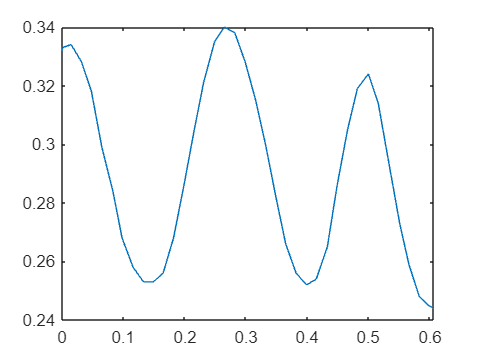

plot(letter.Time,letter.Y)

## Further Practice

Check that your code works for `J.txt` and `V.txt` without having to modify anything except the filename.

letter2=readtable("J.xlsx")

letter2 = 27×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    10256    0.402    0.285    0.011
    10263    0.401    0.286    0.079
    10263    0.401    0.286    0.079
    10280    0.398    0.287    0.218
    10296    0.397    0.286     0.29
    10314    0.397    0.278    0.386
    10330      0.4    0.265    0.489
    10332    0.401    0.261    0.515
    10347    0.404    0.245    0.657
    10364    0.408    0.228    0.831
    10379    0.411    0.212        1
    10397     0.41    0.201        1
    10413    0.407    0.194        1
    10431    0.403    0.192        1
    10447    0.395    0.192        1
    10464    0.387    0.195        1


letter2.X=letter2.X*1.5

letter2 = 27×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

    10256     0.603    0.285    0.011
    10263    0.6015    0.286    0.079
    10263    0.6015    0.286    0.079
    10280     0.597    0.287    0.218
    10296    0.5955    0.286     0.29
    10314    0.5955    0.278    0.386
    10330       0.6    0.265    0.489
    10332    0.6015    0.261    0.515
    10347     0.606    0.245    0.657
    10364     0.612    0.228    0.831
    10379    0.6165    0.212        1
    10397     0.615    0.201        1
    10413    0.6105    0.194        1
    10431    0.6045    0.192        1
    10447    0.5925    0.192        1
    10464    0.5805    0.195        1


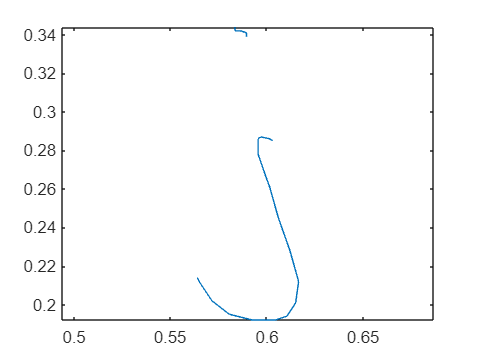

plot(letter2.X,letter2.Y)
axis equal


letter2.Time=(letter2.Time-letter2.Time(1))/1000

letter2 = 27×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0     0.603    0.285    0.011
    0.007    0.6015    0.286    0.079
    0.007    0.6015    0.286    0.079
    0.024     0.597    0.287    0.218
     0.04    0.5955    0.286     0.29
    0.058    0.5955    0.278    0.386
    0.074       0.6    0.265    0.489
    0.076    0.6015    0.261    0.515
    0.091     0.606    0.245    0.657
    0.108     0.612    0.228    0.831
    0.123    0.6165    0.212        1
    0.141     0.615    0.201        1
    0.157    0.6105    0.194        1
    0.175    0.6045    0.192        1
    0.191    0.5925    0.192        1
    0.208    0.5805    0.195        1


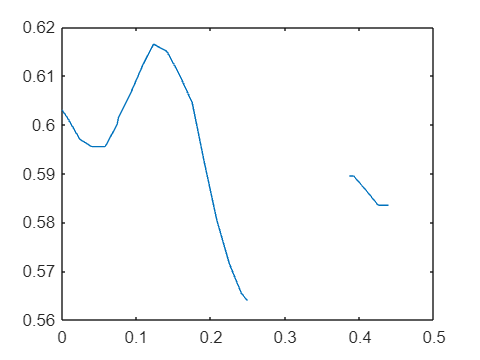

plot(letter2.Time,letter2.X)

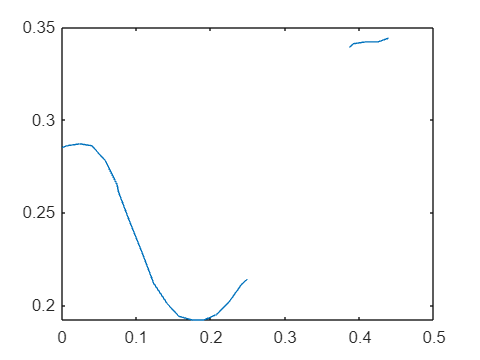

plot(letter2.Time,letter2.Y)

letter3=readtable("V.xlsx")

letter3 = 22×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    13939    0.167    0.255    0.063
    13953    0.167    0.259    0.333
    13953    0.167    0.259    0.333
    13969    0.167     0.26    0.384
    13986    0.167    0.256    0.536
    14003    0.169    0.248    0.622
    14019    0.172    0.232    0.708
    14036    0.175    0.216    0.769
    14052    0.179    0.198    0.856
    14068    0.182    0.186    0.894
    14085    0.184    0.174    0.921
    14102    0.186    0.167     0.94
    14119    0.188    0.168    0.958
    14136    0.189    0.178    0.972
    14152    0.191    0.193    0.974
    14169    0.193    0.218     0.97


letter3.X=letter3.X*1.5

letter3 = 22×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

    13939    0.2505    0.255    0.063
    13953    0.2505    0.259    0.333
    13953    0.2505    0.259    0.333
    13969    0.2505     0.26    0.384
    13986    0.2505    0.256    0.536
    14003    0.2535    0.248    0.622
    14019     0.258    0.232    0.708
    14036    0.2625    0.216    0.769
    14052    0.2685    0.198    0.856
    14068     0.273    0.186    0.894
    14085     0.276    0.174    0.921
    14102     0.279    0.167     0.94
    14119     0.282    0.168    0.958
    14136    0.2835    0.178    0.972
    14152    0.2865    0.193    0.974
    14169    0.2895    0.218     0.97


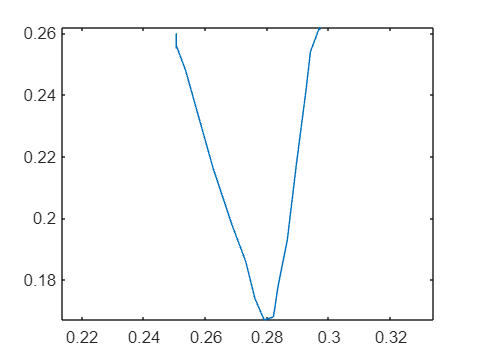

plot(letter3.X,letter3.Y)
axis equal


letter3.Time=(letter3.Time-letter3.Time(1))/1000

letter3 = 22×4 table
    Time       X         Y        P  
    _____    ______    _____    _____

        0    0.2505    0.255    0.063
    0.014    0.2505    0.259    0.333
    0.014    0.2505    0.259    0.333
     0.03    0.2505     0.26    0.384
    0.047    0.2505    0.256    0.536
    0.064    0.2535    0.248    0.622
     0.08     0.258    0.232    0.708
    0.097    0.2625    0.216    0.769
    0.113    0.2685    0.198    0.856
    0.129     0.273    0.186    0.894
    0.146     0.276    0.174    0.921
    0.163     0.279    0.167     0.94
     0.18     0.282    0.168    0.958
    0.197    0.2835    0.178    0.972
    0.213    0.2865    0.193    0.974
     0.23    0.2895    0.218     0.97


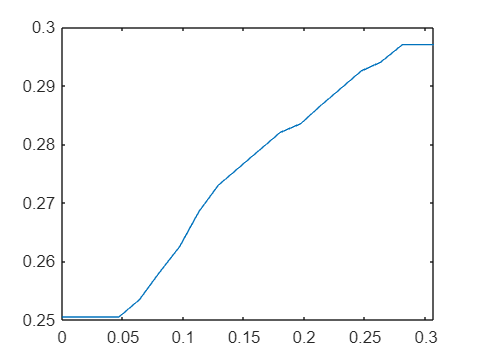

plot(letter3.Time,letter3.X)

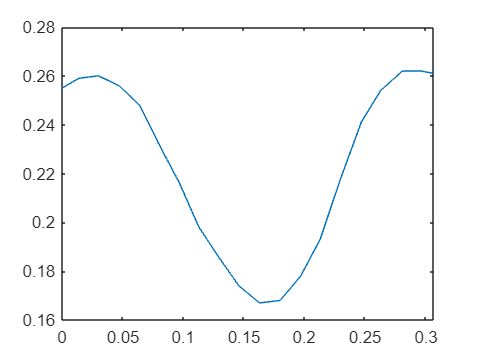

plot(letter3.Time,letter3.Y)